Ejemplo 1

Función de tiempo continuo

t=0:0.001:1; %segundos
f1= 180; %Hz
xt=(2.5/2)*sin(2*pi*f1*t)+1.25;

Gráfica de la señal de tiempo continuo

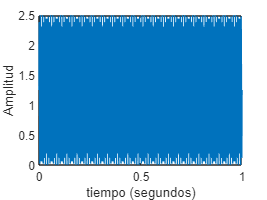

figure
plot(t,xt)
xlabel('tiempo (segundos)')
ylabel('Amplitud')

Discretización de la señal análoga. Se considera un periodo de muestreo de 1/18 de segundo

Ts=1/200; % Periodo de muestreo
nT=0:Ts:2;
xnT=(2.5/2)*sin(2*pi*f1*nT)+1.25;

Gráfica de la señal discretizada

Observe que la unidad de tiempo aun no ha cambiado, siguen siendo segundos. Cada muestra está ubicada en el instante de tiempo donde se captura el valor de la señal análoga

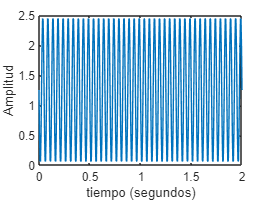

figure
%stem(nT,xnT);
plot(nT,xnT)
dlmwrite('M180hz.txt',xnT);
xlabel('tiempo (segundos)')
ylabel('Amplitud')

En la siguiente gafica se observa la superposición de las muestras capturadas con la señal análoga

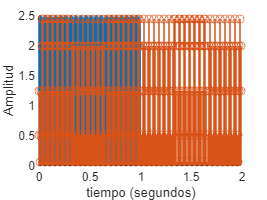

figure
hold on
plot(t,xt)
stem(nT,xnT)
xlabel('tiempo (segundos)')
ylabel('Amplitud')

A continuación se obtendrá la señal de tiempo discreto (digital). La frecuencia de muestreo (Fs) es el inverso multiplicativo del periodo de muestreo. Se consideran 18 muestras para representar la señal

Fs=1/Ts;
N=Fs;
n=0:N;
xn=2.5*sin(2*pi*(f1/Fs)*n)+1.25;
j=5;

%writematrix(xn);
%type 'm10hz.txt';

Gráfica de la señal de tiempo discreto (digital). Se observa que la unidad de tiempo es diferente, ahora son muestras y corresponden a valores enteros

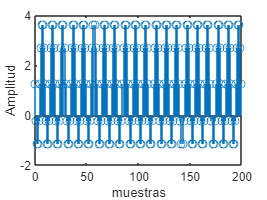

figure,
stem(n,xn)
xlabel('muestras')
ylabel('Amplitud')